
count=1;
iteration=1;
I=xlsread('input.xlsx',1);
To=xlsread('targetoutput.xlsx',1);
h=xlsread('nofpattern.xlsx',1);
Ta=xlsread('testingdata.xlsx');

Tol=0.0001;%tolerance value
l=3;%no of  input neurons
m=6;%no of hidden neurons
n=2;% no of output neurons
V=rand(l+1,m);
MSE=40; eta=0.3; alpha=0.1;
W=rand(m+1,n);
In=zeros(l,h);
Ton=zeros(n,h);
delW0=zeros(m+1,n);
delV0=zeros(l+1,m);
while MSE>Tol
    %normalisation of input matrix from 0.1 to 0.9
    for i=1:l
       minel=min(I(i,:));
       maxel=max(I(i,:));
      for P=1:h
         
       In(i,P)=0.1+0.8*((I(i,P)-minel)/(maxel-minel));
      end 
    end

 for j=1:n
       minel=min(To(j,:));
       maxel=max(To(j,:));
      for P=1:h
         
       Ton(j,P)=0.1+0.8*((To(j,P)-minel)/(maxel-minel));
      end 
  
 end 
IH=zeros(m,h);   
In1=[1 1 1 1 1 1 1 1;In];
%calculating input matrix to hidden neurons
IH=In1'*V;
IH1=IH';%transpose of IH of dimension 8*6
OH=zeros(m,h);% output of hidden neurons
for j=1:m
    for P=1:h
        
        OH(j,P)=1/(1+exp(-IH1(j,P)));
        
    end
end
Io=zeros(n,h);
OH1=[1 1 1 1 1 1 1 1;OH];%making dimension of output matrix of hidden layer M*P to (M+1)*P by adding bias row of value 1
Io=(OH1')*W;
Io1=Io';%taking transpose to reverse the dimension
Oo=zeros(n,h);
for   P=1:h
     for k=1:n
         Oo(k,P)=1/(1+exp(-Io1(k,P)));
         
     end
end

%calculating error matrix
Error=zeros(n,h);MSE=0;
for k=1:n
    for P=1:h
        Error(k,P)=0.5*(Ton(k,P)-Oo(k,P))^2;
        MSE=MSE+Error(k,P);
    end
end



delW=zeros(m+1,n) ;

     for j=1:m+1
         for k=1:n
             sum=0;
             for P=1:h
                 
                 
                 x=Ton(k,P)-Oo(k,P);
               
                 z=Oo(k,P)*(1-Oo(k,P))*OH1(j,P);
                sum=sum+(x*z);
             end
             
              moment=alpha*delW0(j,k);
                 delW(j,k)=delW(j,k)+(eta/h)*sum +moment;
         end
     end
     delW0=delW;
     W=W+delW;
     
     delV=zeros(l+1,m);
     for i=1:l+1
         for j=1:m
             
               sum1=0;
             for k=1:n
               
                 for P=1:h
                    
                 
                 x1=Ton(k,P)-Oo(k,P);
               
                 z1=Oo(k,P)*(1-Oo(k,P))*W(j,k)*OH1(j,P)*(1-OH(j,P)*In1(i,P));
                sum1=sum1+(x1*z1);
                     
                 end
                 sum2=0;
                 sum2=sum2+sum1;
             end
             moment=alpha*delV0(i,j);
             delV(i,j)=delV(i,j)+((eta/(h*n))*sum2)+moment;
             
             
         end
     end
     delV0=delV;
     V=V+delV;
     MSE=MSE/(n*h);
     
    
     A(count)=MSE;
     count=count+1;
    
     iteration=iteration+1;
   
end

%Testing the data with existing input normalised data
 %normalisation of input matrix from 0.1 to 0.9
    for i=1:l
       minel=min(I(i,:));
       maxel=max(I(i,:));
      for P=1:h
         
       In(i,P)=0.1+(0.8*(I(i,P)-minel)/(maxel-minel));
      end 
    end
 % normalised target value between 0.1 to 0.9
 for j=1:n
       minel=min(To(j,:));
       maxel=max(To(j,:));
      for P=1:h
         
       Ton(j,P)=0.1+(0.8*(To(j,P)-minel)/(maxel-minel));
      end 
  
 end 
    
In1=[1 1 1 1 1 1 1 1;In];
%calculating input matrix to hidden neurons
IH=In1'*V;
IH1=IH';%transpose of IH of dimension 8*6
OH=zeros(m,h);% output of hidden neurons
for j=1:m
    for P=1:h
        
        OH(j,P)=1/(1+exp(-IH1(j,P)));
        
    end
end
OH1=[1 1 1 1 1 1 1 1;OH];%making dimension of output matrix of hidden layer M*P to (M+1)*P by adding bias row of value 1
Io=OH1'*W;
Io1=Io';%taking transpose to reverse the dimension
Oo=zeros(n,h);
for   P=1:h
     for k=1:n
         Oo(k,P)=1/(1+exp(-Io1(k,P)));
         
     end
end


%Denormalising the output matrix of output layer (Oop)
Oop=zeros(n,h);
 for k=1:n
       minel=min(To(k,:));
       maxel=max(To(k,:));
      for P=1:h
         
         Oop(k,P)=minel+((Oo(k,P))*(maxel-minel));
      end 
  
 end 
%Calculating the error matrix
Err=zeros(n,h);
for P=1:h
    for k=1:n
        Err(k,P)=abs(1-Oop(k,P)/To(k,P));
    end
end
MSE % mean square error

MSE = 1.0000e-04

iteration % no of iteration 

iteration = 972626

To %Target values

To =     27    32    36    38    48    59    66    67
    41    48    58    61    67    74    76    79


Oop %predicted output

Oop =    31.4138   34.8394   37.3602   40.7924   47.6693   56.3308   61.6724   63.9850
   44.8586   50.5275   57.7127   61.5752   65.4807   70.7931   73.3877   74.8972


Err % relative error calculated between To and Oop 

Err =     0.1635    0.0887    0.0378    0.0735    0.0069    0.0452    0.0656    0.0450
    0.0941    0.0527    0.0050    0.0094    0.0227    0.0433    0.0344    0.0519


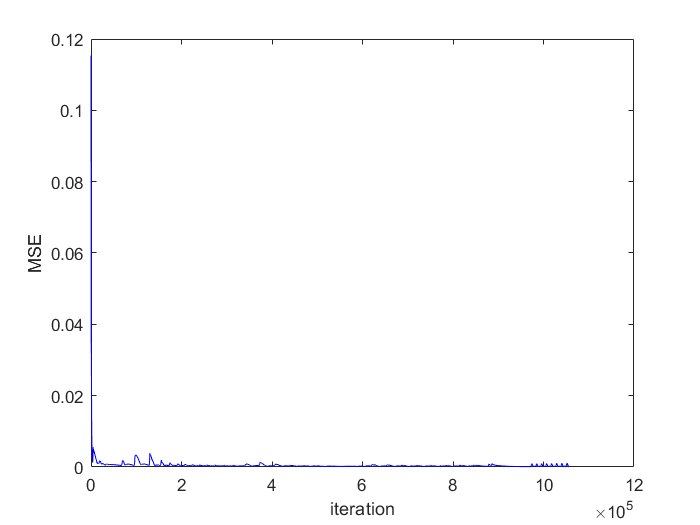

plot(A(),"b-");
xlabel("iteration");
ylabel("MSE");